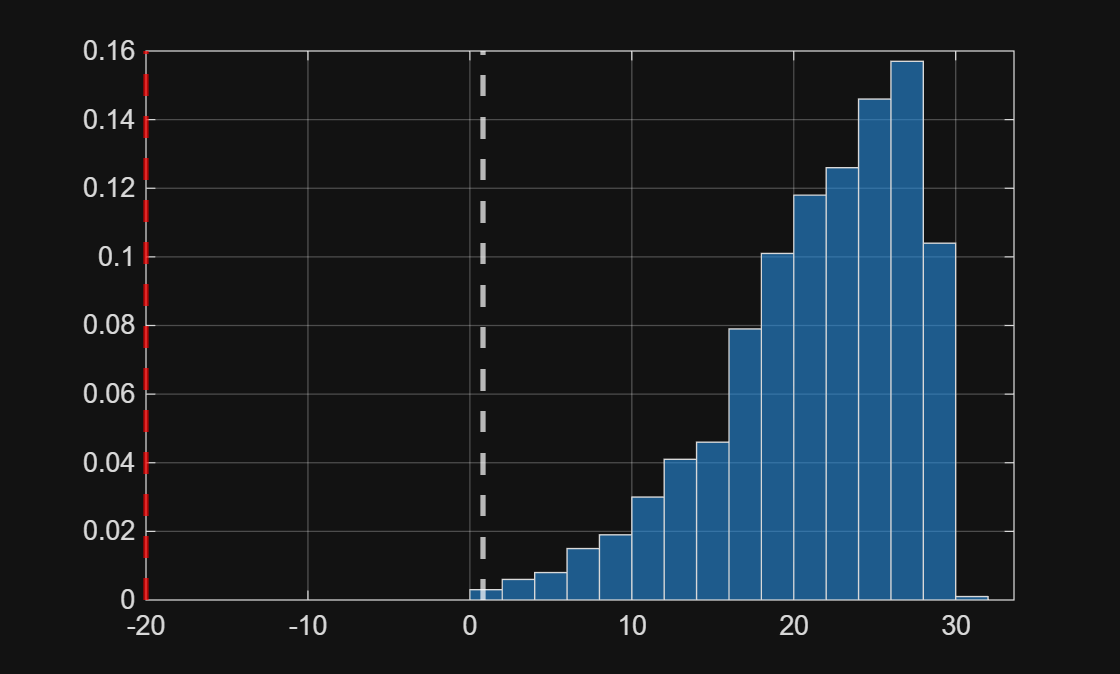

N = 1000;
PD = 0.1;
Detections = rand(N,1)<PD;
Life = (1:N)';
StepsSinceLastDetection = zeros(N,1);
for n = 2 : N
    if Detections(n)
        StepsSinceLastDetection(n) = 0;
    else
        StepsSinceLastDetection(n) = StepsSinceLastDetection(n-1) + 1;
    end
end

histogram(10*log10((1+Life).*(1-PD).^(StepsSinceLastDetection)),"Normalization","probability")
hold on
xline(min(10*log10((1+Life).*(1-PD).^(StepsSinceLastDetection))),LineWidth=2,Color='w',LineStyle='--')
xline(-20,LineWidth=2,Color='r',LineStyle='--')
grid on
hold off